# Integration - Romberg Integration


$$I = \int_a^b{f\left( x \right) dx}$$


- integral function: $f\left( x \right)$

- upper limit: $b$

- lower limit: $a$

- number of splited intervals: $h,N;\,x_0,x_1,...,x_N;\,\,f_0,f_1,...,f_N
$

(Personal view) these two methods are same

- Richardson extrapolation wiki: [https://en.wikipedia.org/wiki/Richardson_extrapolation](https://en.wikipedia.org/wiki/Richardson_extrapolation)

- Romberg Integration wiki: [https://en.wikipedia.org/wiki/Romberg%27s_method](https://en.wikipedia.org/wiki/Romberg%27s_method)

**power series expansion**: $$$
I\left( h \right) =I+a_1h^2+a_2h^4+...+a_kh^{2k}+...
$$
$

**approximation**: $$$
I=\lim_{h\rightarrow 0} I\left( h \right) 
$$

$

**extrapolation method**: given$$$
I\left( h \right) 
$$

$ for $$$
h=b-a,\frac{b-a}{2},\frac{b-a}{4},...,\frac{b-a}{2^N}
$$
$, we are required to estimate the value for $$$
h=0
$$
$, which is not in the range from $$$
\frac{b-a}{2^N}
$$
$ to $$$
b-a
$$
$

## Naive version Romberg Integration - linear equations


$$$$\begin{array}{ccc}
I\left( b-a \right) &=&I+a_1\left( b-a \right) ^2+a_2\left( h-a \right) ^4+a_N\left( b-a \right) ^{2N}\\
I\left( \frac{b-a}{2} \right) &=&I+a_1\left( \frac{b-a}{2} \right) ^2+a_2\left( \frac{b-a}{2} \right) ^4+a_N\left( \frac{b-a}{2} \right) ^{2N}\\
&...&\\
I\left( \frac{b-a}{2^N} \right) &=&I+a_1\left( \frac{b-a}{2^N} \right) ^2+a_2\left( \frac{b-a}{2^N} \right) ^4+a_N\left( \frac{b-a}{2^N} \right) ^{2N}
\end{array}$$$$


In matrix form


$$$$
\left( \matrix{
	1&		\left( b-a \right) ^2&		\left( b-a \right) ^4&		...&		\left( b-a \right) ^{2N} \cr
	1&		\left( \frac{b-a}{2} \right) ^2&		\left( \frac{b-a}{2} \right) ^4&		...&		\left( \frac{b-a}{2} \right) ^{2N} \cr
	1&		\left( \frac{b-a}{4} \right) ^2&		\left( \frac{b-a}{4} \right) ^4&		...&		\left( \frac{b-a}{4} \right) ^{2N} \cr
	\vdots&		\vdots&		\vdots&		\ddots&		\vdots \cr
	1&		\left( \frac{b-a}{2^N} \right) ^2&		\left( \frac{b-a}{2^N} \right) ^4&		...&		\left( \frac{b-a}{2^N} \right) ^{2N} \cr
} \right)
\left( \begin{array}{c}
	I\\
	a_1\\
	a_2\\
	\vdots\\
	a_N\\
\end{array} \right) =\left( \begin{array}{c}
	I\left( b-a \right)\\
	I\left( \frac{b-a}{2} \right)\\
	I\left( \frac{b-a}{4} \right)\\
	\vdots\\
	I\left( \frac{b-a}{2^N} \right)\\
\end{array} \right) 
$$
$$


Vandermonde matrix: [https://en.wikipedia.org/wiki/Vandermonde_matrix](https://en.wikipedia.org/wiki/Vandermonde_matrix)

## Romberg Integration

Recursive formula: $$$
R_{n-1m}=\frac{4^mR_{nm-1}-R_{n-1m-1}}{4^m-1}
$$
$

denote

- 
$$$$
h=b-a
$$
$$


- 
$$$$
R_{00}=I\left( h \right) ,R_{10}=I\left( h/2 \right) ,...,R_{N0}=I\left( h/2^N \right) 
$$
$$



$$$$
\left( \matrix{
	1&		h^2&		h^4&		...&		h^{2N}\cr
	1&		\left( h/2 \right) ^2&		\left( h/2 \right) ^4&		...&		\left( h/2 \right) ^{2N}\cr
	1&		\left( h/4 \right) ^2&		\left( h/4 \right) ^4&		...&		\left( h/4 \right) ^{2N}\cr
	\vdots&		\vdots&		\vdots&		\ddots&		\vdots\cr
	1&		\left( h/2^N \right) ^2&		\left( h/2^N \right) ^4&		...&		\left( h/2^N \right) ^{2N}\cr
} \right) \left( \begin{array}{c}
	I\\
	a_1\\
	a_2\\
	\vdots\\
	a_N\\
\end{array} \right) =\left( \begin{array}{c}
	R_{00}\\
	R_{10}\\
	R_{20}\\
	\vdots\\
	R_{N0}\\
\end{array} \right) 
$$
$$


First Iteration: $$$
R_{01}=\frac{4R_{10}-R_{00}}{3},R_{11}=\frac{4R_{20}-R_{10}}{3},...,R_{N-11}=\frac{4R_{N0}-R_{N-10}}{3}
$$
$


$$$$
\left( \matrix{
	1&		h^2&		h^4&		...&		h^{2N-2}\cr
	1&		\left( h/2 \right) ^2&		\left( h/2 \right) ^4&		...&		\left( h/2 \right) ^{2N-2}\cr
	1&		\left( h/4 \right) ^2&		\left( h/4 \right) ^4&		...&		\left( h/4 \right) ^{2N-2}\cr
	\vdots&		\vdots&		\vdots&		\ddots&		\vdots\cr
	1&		\left( h/2^{N-1} \right) ^2&		\left( h/2^{N-1} \right) ^4&		...&		\left( h/2^{N-1} \right) ^{2N-2}\cr
} \right) \left( \begin{array}{c}
	I\\
	b_1\\
	b_2\\
	\vdots\\
	b_{N-1}\\
\end{array} \right) =\left( \begin{array}{c}
	R_{01}\\
	R_{11}\\
	R_{21}\\
	\vdots\\
	R_{N-11}\\
\end{array} \right) 
$$
$$


Repeat recursive formula


$$$$
I=R_{0N}=\frac{4^NR_{1N-1}-R_{0N-1}}{4^N-1}
$$
$$


## paramter

hf1 = @(x) (3-x-x.^2).*sin(x).^2;
a = -1;
b = 1;

### plot integral area

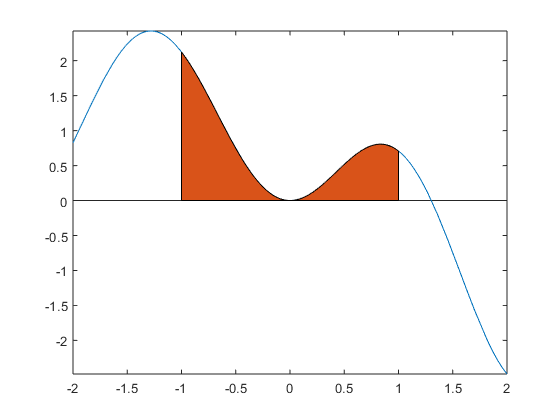

figure()
fplot(hf1, [a-1,b+1])
hold on;
area(linspace(a,b), hf1(linspace(a,b)))
hold off

## built-in

ret1 = integral(hf1, a, b); %doc('integral')
disp(['built-in integral: ', num2str(ret1,14)])

built-in integral: 1.321971464861


## naive Romberg integration

ret1 = my_naive_romberg_integral(hf1, a, b, 6);
disp(['naive Romberg integral: ', num2str(ret1,14)])

naive Romberg integral: 1.321971464861


## Romberg Integration

ret1 = my_romberg_integral(hf1, a, b, 6);
disp(['Romberg integral: ', num2str(ret1,14)])

Romberg integral: 1.321971464861


## function

function ret = my_naive_romberg_integral(hf1, a, b, m)
% naive Romberg Integration: solve linear equations directly
% reference: https://en.wikipedia.org/wiki/Romberg%27s_method
% hf1(function handle)
% a(float)
% b(float)
% m(int)
% ret(float)
R = zeros(1,m+1);
h = b-a;
R(1) = h/2*(hf1(a) + hf1(b));
for ind1 = 1:m
    tmp1 = hf1(a + h*(1:2:(2^ind1-1))/2^ind1);
    R(ind1+1) = R(ind1)/2 + h/2^ind1*sum(tmp1);
    %equivalent to my_trapezoidal_integral(hf1, a, b, 2^ind1+1)
end

matA = (h./(2.^(0:m)).').^(0:2:2*m);
tmp1 = matA\(R.');
ret = tmp1(1);
end

function R = my_romberg_integral(hf1, a, b, m)
% calculate integration using Romberg's method
% reference: https://en.wikipedia.org/wiki/Romberg%27s_method
% hf1(function handle)
% a(float)
% b(float)
% m(int)
% ret(float)
R = zeros(1,m+1);
h = b-a;
R(1) = h/2*(hf1(a) + hf1(b));
for ind1 = 1:m
    tmp1 = hf1(a + h*(1:2:(2^ind1-1))/2^ind1);
    R(ind1+1) = R(ind1)/2 + h/2^ind1*sum(tmp1);
    %equivalent to my_trapezoidal_integral(hf1, a, b, 2^ind1+1)
end
for ind1 = 1:m
    R = R(2:end) + (R(2:end) - R(1:end-1))/(4^ind1-1);
end
end
